 module_ofdm.m

Script principal du projet OFDM.

Etapes:

1) Initialiser l'environnement et la configuration.

2) Ouvrir le bladeRF.

3) Executer TX + synchro TX/RX + RX.

4) Fermer proprement le bladeRF.


clear; clc; close all;

## Preparation de l'environnement

config = default_ofdm_config();
addpath(config.bladeRFMatlabDir);
if ~contains(lower(getenv('PATH')), lower(config.bladeRFRoot))
    setenv('PATH', [config.bladeRFRoot ';' getenv('PATH')]);
end

## Ouverture du bladeRF

try
    b = bladeRF();
    fprintf('bladeRF ouvert avec succes.\n');
    fprintf('  Serial : %s\n', strtrim(b.info.serial));
catch ME
    fprintf(2, 'Erreur a l''ouverture du bladeRF:\n%s\n', ME.message);
    b = [];
end

bladeRF ouvert avec succes.


  Serial : 5a57974b84b448c69bb7c9b3b11371a6 


## Chaine TX, synchronisation TX/RX et chaine RX

Pipeline principal: - module_tx: construit la trame OFDM. - synchronize_tx_rx: emet et capture en mode timestamp. - module_rx: analyse/affiche les echantillons recus.

module_tx: 2304 bits generes pour transmission (576 symboles).
module_tx: [576 x 1] symbols generes.
module_tx: conversion serie-parallele [48 x 12] et mapping sous-porteuses termine.
module_tx: IFFT + CP termines (960 echantillons payload).
module_tx: preambule insere (320 echantillons). Trame TX totale: 1280 echantillons.
module_tx: buffer TX prepare (normalisation 1.444).


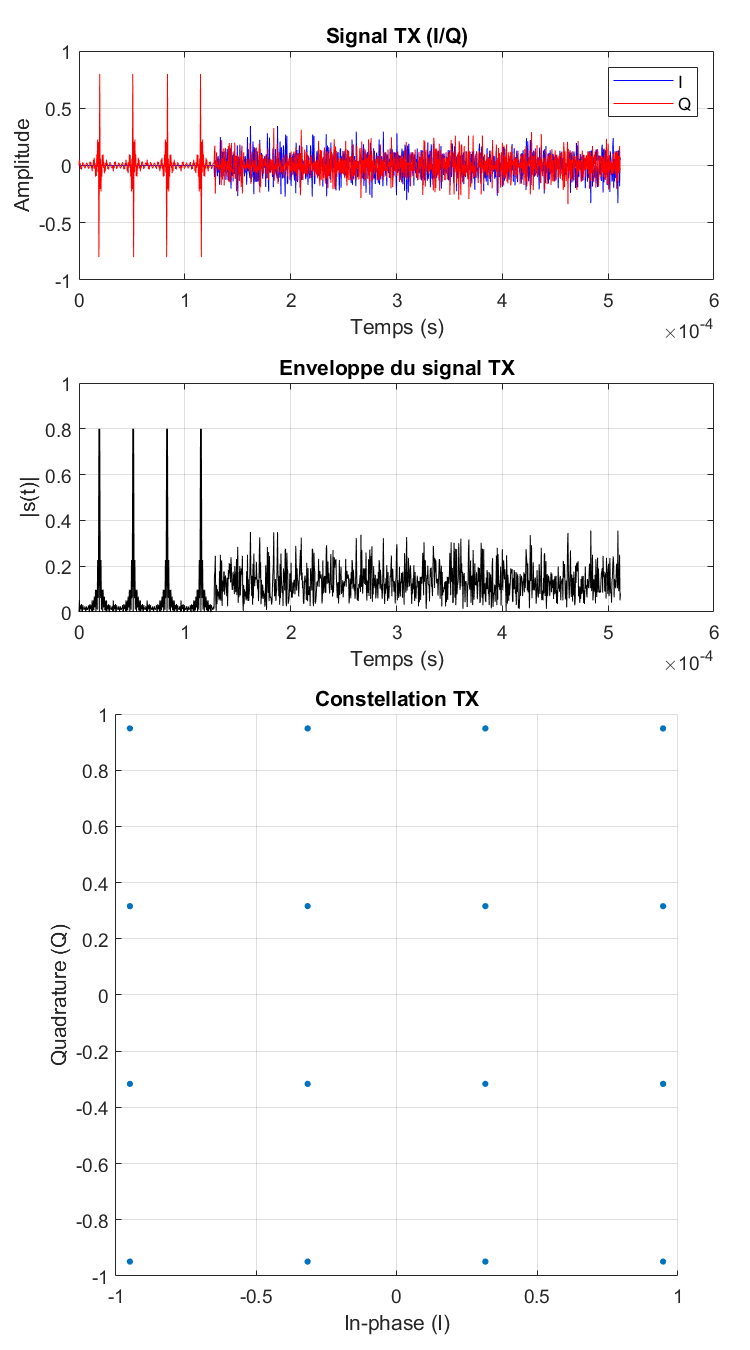

module_tx: visualisation TX affichee (1280 echantillons).


txContext     = module_tx(config);

rawRxSamples  = synchronize_tx_rx(b, txContext, config);

module_ofdm: synchro TX/RX (t0=626719, RX=601719, 51280 echantillons).


module_ofdm: burst TX envoye (1280 echantillons).
module_ofdm: 51280 echantillons captures (ts=601719).


module_rx: 51280 echantillons fournis pour traitement RX.
module_rx: mean|s|=0.0075, rms|s|=0.0107, max|s|=0.2848.
module_rx: affichage centre sur le burst (echantillons 24868 a 26867).


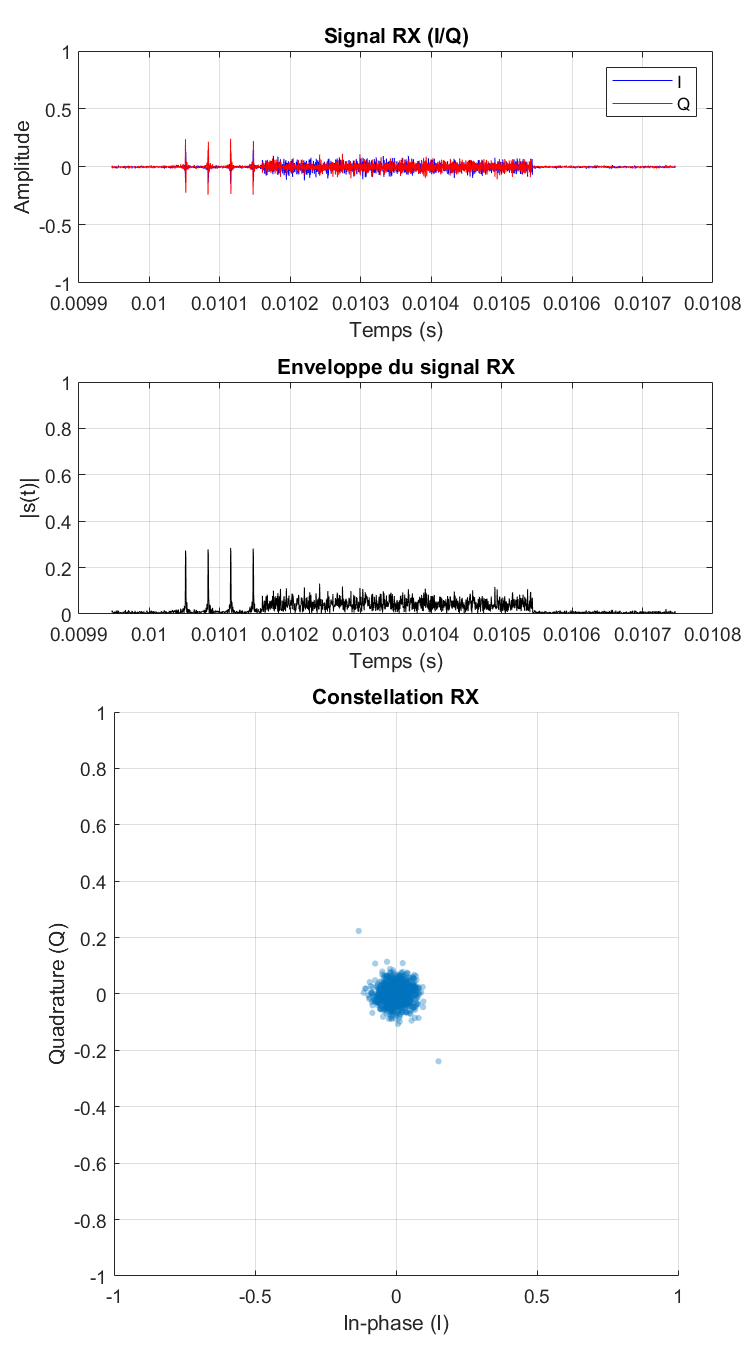

module_rx: visualisation RX affichee (2000 echantillons autour du burst).


rxContext      = module_rx(rawRxSamples, config, txContext); %#ok<NASGU>

## Fermeture du bladeRF

if ~isempty(b)
    try
        delete(b);
        clear b;
        fprintf('bladeRF ferme avec succes.\n');
    catch MEclose
        fprintf(2, 'Erreur a la fermeture du bladeRF:\n%s\n', MEclose.message);
    end
end

bladeRF ferme avec succes.


## -----------------------------------------------------------------------

function config = default_ofdm_config()
    % Parametres globaux centralises (RF + OFDM + synchronisation).
    config.bladeRFRoot      = 'C:\Users\yoyol\OneDrive\UQTR-Yohan\1-Systèmes de télécommunications\Projet';
    config.bladeRFMatlabDir = fullfile(config.bladeRFRoot, 'matlab');

    % Parametres RF
    config.centerFrequencyHz = 2.45e9;
    config.sampleRateHz      = 2.5e6;
    config.bandwidthHz       = 2.5e6;
    config.txGainDb          = 30;
    config.syncLeadTimeMs    = 250;  % Marge avant le burst TX (ms)
    config.rxPrerollMs       = 10;   % Capture avant le burst (ms)
    config.rxPostrollMs      = 10;   % Capture apres le burst (ms)
    config.streamTimeoutMs   = 5000;

    % Parametres OFDM
    config.N_FFT   = 64;
    config.N_VC    = 16;
    config.N_USED  = config.N_FFT - config.N_VC;
    config.N_CP    = config.N_FFT / 4;
    config.N_SYM   = 12;
    config.N_PREA  = 4;
    config.M_ORDER = 16;

    K = config.N_USED / 2;
    config.data_bins_shift = [(-K):-1 1:K];
end


function rawSamples = synchronize_tx_rx(radio, txContext, config)
% Configurer la radio puis planifier TX et RX sur la meme horloge.
% Principe: RX demarre avant TX (preroll) pour ne pas rater le burst.

    rawSamples = [];
    if isempty(radio)
        warning('module_ofdm: aucun bladeRF fourni.');
        return;
    end

    fs = config.sampleRateHz;

    % --- Configuration RF (commune TX et RX) ---
    radio.rx.frequency  = config.centerFrequencyHz;
    radio.tx.frequency  = config.centerFrequencyHz;
    radio.rx.samplerate = fs;
    radio.tx.samplerate = fs;
    radio.rx.bandwidth  = config.bandwidthHz;
    radio.tx.bandwidth  = config.bandwidthHz;
    radio.rx.config.timeout_ms = config.streamTimeoutMs;
    radio.tx.config.timeout_ms = config.streamTimeoutMs;
    radio.tx.gain = config.txGainDb;

    % --- Calcul des tailles et timestamps ---
    % preroll/postroll = marge avant/apres le burst TX.
    tx_len   = numel(txContext.txBuffer);
    preroll  = round(config.rxPrerollMs  * fs / 1000);
    postroll = round(config.rxPostrollMs * fs / 1000);
    rx_len   = tx_len + preroll + postroll;

    radio.tx.start();
    tx_ts = uint64(double(radio.rx.timestamp) + round(config.syncLeadTimeMs * fs / 1000));
    rx_ts = uint64(max(0, double(tx_ts) - preroll));

    fprintf('module_ofdm: synchro TX/RX (t0=%u, RX=%u, %d echantillons).\n', tx_ts, rx_ts, rx_len);

    % --- Lancer la capture RX sur un worker parallele ---
    % Le worker prepare RX en parallele pour fiabiliser la synchro.
    rx_future = [];
    try
        pool = gcp('nocreate');
        if isempty(pool), pool = parpool('local', 1); end
        rx_future = parfeval(pool, @bladerf_parallel_rx_worker, 4, ...
            strtrim(radio.info.serial), config, rx_ts, rx_len);
        fprintf('module_ofdm: worker RX parallele lance (%d echantillons).\n', rx_len);
    catch ME
        warning('module_ofdm:noParallel', 'Worker RX indisponible: %s', ME.message);
    end

    % --- Emettre le burst TX ---
    radio.transmit(double(txContext.txBuffer(:)), config.streamTimeoutMs, tx_ts, true, true);
    fprintf('module_ofdm: burst TX envoye (%d echantillons).\n', tx_len);

    % --- Recuperer les echantillons RX ---
    if ~isempty(rx_future)
        % Cas nominal: lecture des echantillons du worker parallele.
        [samples, ts_out, actual_count, overrun] = fetchOutputs(rx_future);
        cancel(rx_future);
    else
        % Fallback sequentiel si le worker n'a pas pu demarrer
        radio.rx.start();
        [samples, ts_out, actual_count, overrun] = radio.receive(rx_len, config.streamTimeoutMs, rx_ts);
        radio.rx.stop();
    end

    rawSamples = samples(:);
    if actual_count > 0 && actual_count < numel(rawSamples)
        rawSamples = rawSamples(1:actual_count);
    end

    fprintf('module_ofdm: %d echantillons captures (ts=%u).\n', numel(rawSamples), ts_out);
    if overrun
        warning('module_ofdm:rxOverrun', 'Overrun detecte pendant la capture RX.');
    end

    radio.tx.stop();
end